## Simulation of evolution of populations of hBN

### Using the 3-level model

clear 
clc
close all

K0 = zeros(3,3);
beta = 0.05;
k_21 = 281.5;
k_12 = beta * k_21;
k_23 = 14.73;
k_31 = 44.95;
K0(1,2) = k_12;
K0(2,1) = k_21;
K0(2,3) = k_23;
K0(3,1) = k_31;

K0_ON = K0;     %K matrix when laser is on

ode1_ON = @(t, y) K0_ON(1,1)*y(1) - K0_ON(1,1)*y(1)...
                 + K0_ON(2,1)*y(2) - K0_ON(1,2)*y(1)...
                 + K0_ON(3,1)*y(3) - K0_ON(1,3)*y(1);
ode2_ON = @(t, y) K0_ON(1,2)*y(1) - K0_ON(2,1)*y(2)...
                 + K0_ON(2,2)*y(2) - K0_ON(2,2)*y(2)...
                 + K0_ON(3,2)*y(3) - K0_ON(2,3)*y(2);
ode3_ON = @(t, y) K0_ON(1,3)*y(1) - K0_ON(3,1)*y(3)...
                 + K0_ON(2,3)*y(2) - K0_ON(3,2)*y(3)...
                 + K0_ON(3,3)*y(3) - K0_ON(3,3)*y(3);

odes_ON = @(t, n) [ode1_ON(t, n); ode2_ON(t, n); ode3_ON(t, n)];

init_ON = [1; 0; 0];
[t, n_res_ON] = ode45(odes_ON, [0 : 1e-4 : 1e-1], init_ON);

% plot(t, n_res_ON, 'LineWidth',1.5);
% xlabel('Time (\mus)');
% ylabel('Populations');
% legend('n_1', 'n_2', 'n_3');

n_res_2 = n_res_ON(:, 2);
tau_arr = 0 : 1e-4 : 8e-2;
length = size(tau_arr);
g2_arr = zeros(length);
for i = 1 : length(2)
    g2_arr(i) = n_res_2(i) / n_res_2(end);
end

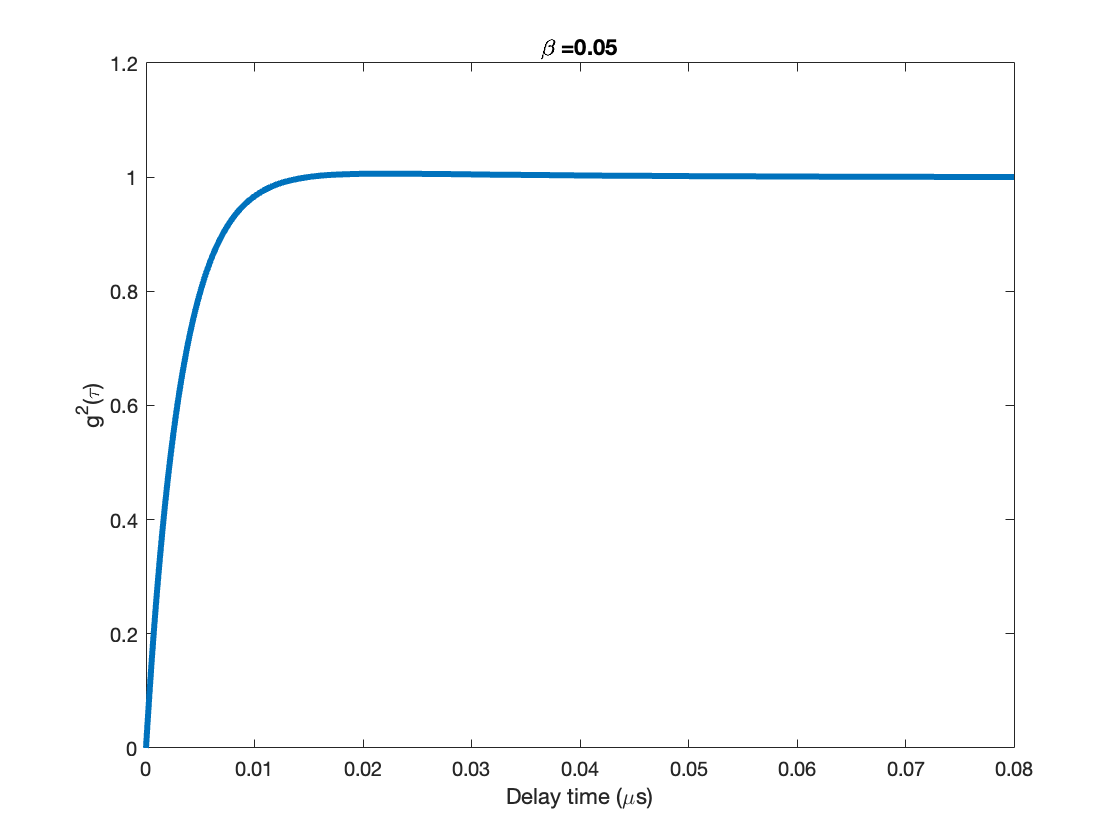

plot(tau_arr, g2_arr, 'LineWidth',3);
xlabel('Delay time (\mus)');
ylabel('g^2(\tau)');
name1 = '\beta = ';
name2 = num2str(beta);
name = strcat(name1, ' ', name2);
title(name);

tau_arr = tau_arr';
g2_arr = g2_arr';

### Randomizing the data 

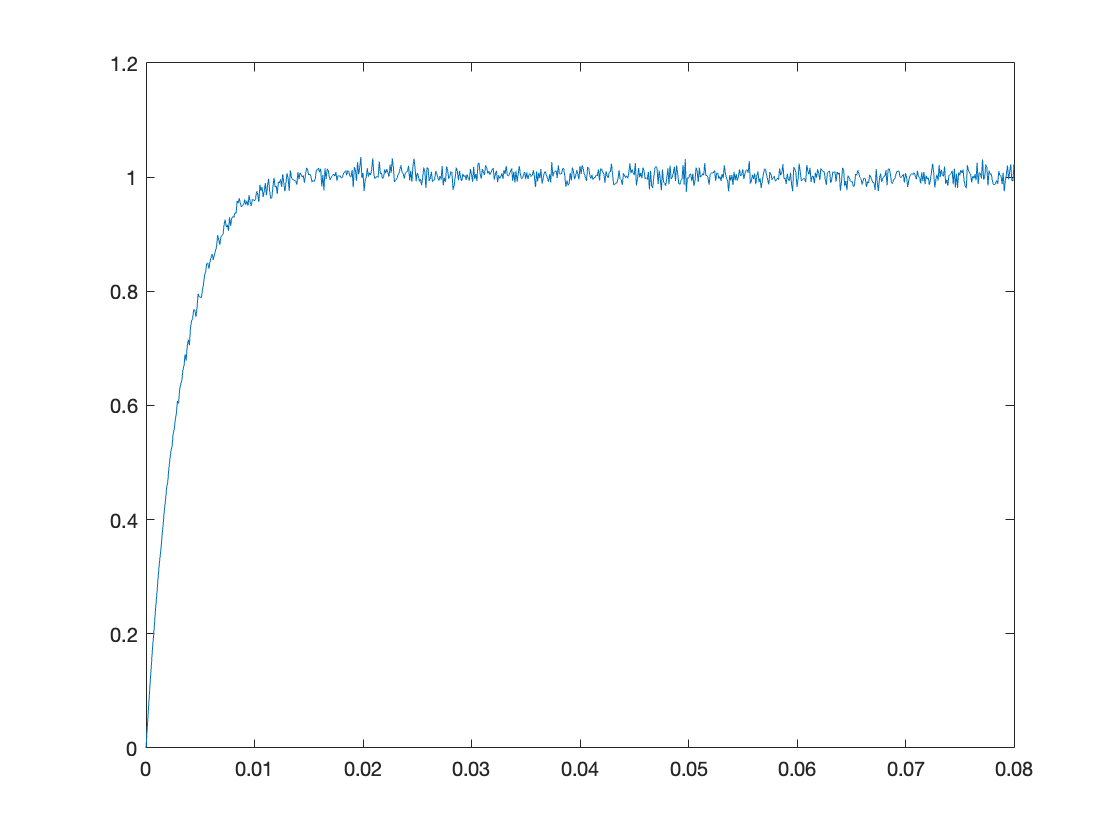

x = randn;

for i = 1 : size(g2_arr)
    stdev = 0.01 * g2_arr(i);
    g2_arr(i) = g2_arr(i) +  stdev * randn; 
end
plot(tau_arr, g2_arr)

#### curve fitting for seven level model

ft = fittype('seven_state_g2(x, k0_r, k0_47, k0_57, k0_71)');
f = fit(tau_arr, g2_arr, ft, 'StartPoint', [k_21, 0, k_23, k_31])

f =      General model:
     f(x) = seven_state_g2(x, k0_r, k0_47, k0_57, k0_71)
     Coefficients (with 95% confidence bounds):
       k0_47 =       46.71  (-10.66, 104.1)
       k0_57 =       27.58  (-12.3, 67.47)
       k0_71 =       24.53  (-0.7501, 49.81)
       k0_r =       267.5  (224.7, 310.4)

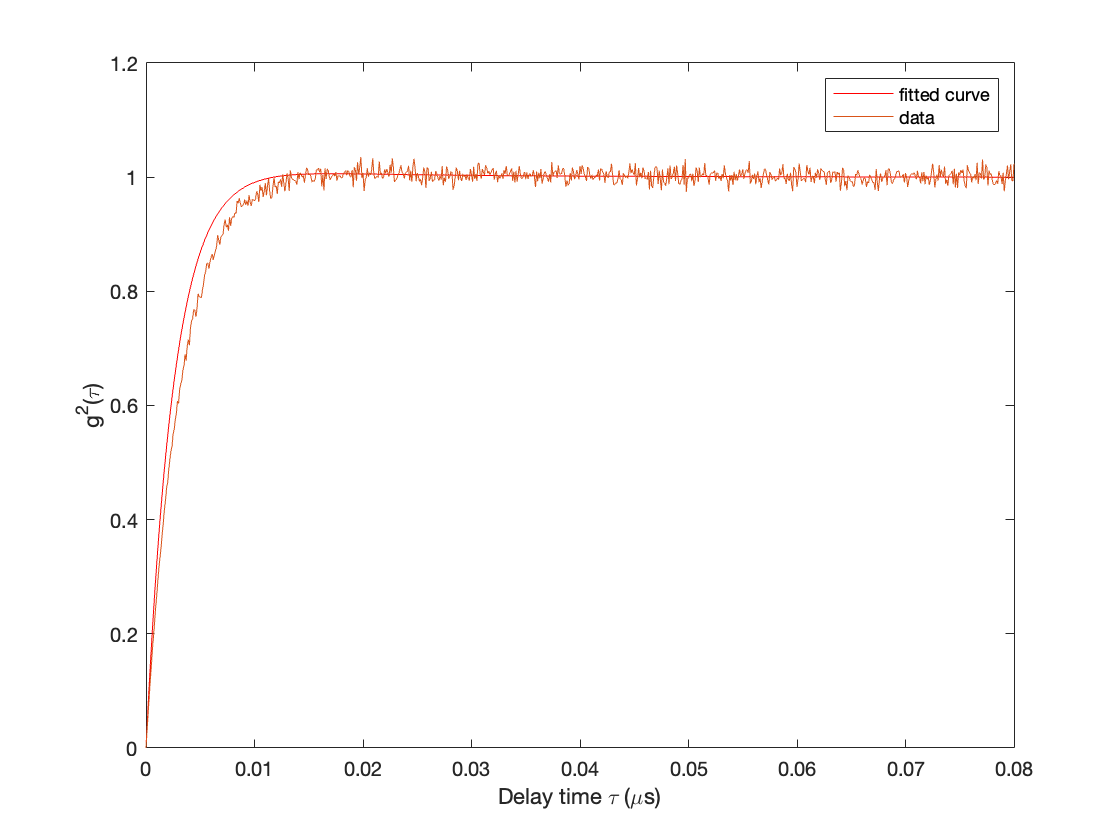

% plot(f, tau_arr, g2_arr)
plot(f)
hold on
plot(tau_arr, g2_arr)
hold off
xlabel('Delay time \tau (\mus)');
ylabel('g^2(\tau)');
legend('fitted curve', 'data')

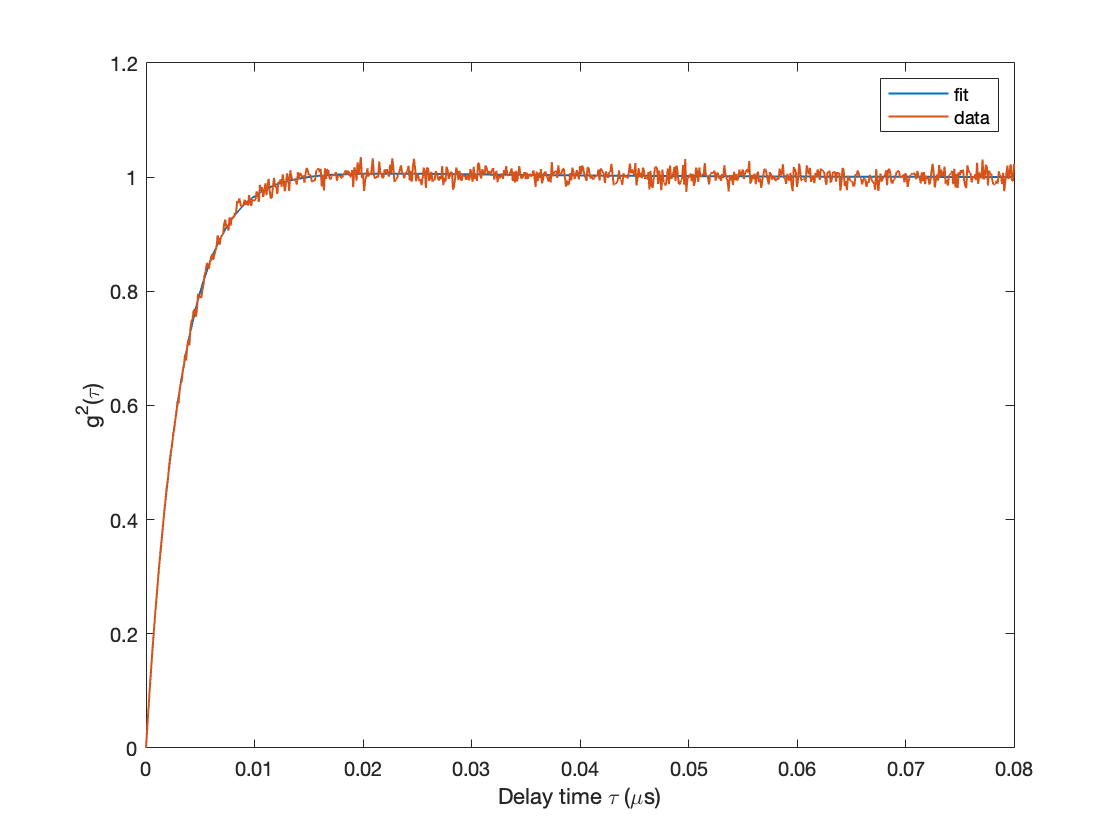

g2_from_func = seven_state_g2(tau_arr, 281.5, 14.73, 14.73, 14.98);
plot(tau_arr, g2_from_func, 'LineWidth', 1)
hold on
plot(tau_arr, g2_arr, 'LineWidth', 1)
legend('fit', 'data');
hold off
xlabel('Delay time \tau (\mus)');
ylabel('g^2(\tau)');

### curve fitting for three level model

% ft = fittype('three_state_g2( x, k_21, k_23, k_31)');
% f = fit(tau_arr, g2_arr, ft, 'StartPoint', [k_21, k_23, k_31])
% % plot(f, tau_arr, g2_arr)
% plot(f)
% hold on
% plot(tau_arr, g2_arr)
% hold off
% xlabel('Delay time \tau (\mus)');
% ylabel('g^2(\tau)');
% legend('fitted curve', 'data');

% g2_from_func = three_state_g2(tau_arr, 284.1, 13.55, 42.2);
% plot(tau_arr, g2_from_func, 'LineWidth', 1)
% hold on
% plot(tau_arr, g2_arr, 'LineWidth', 1)
% legend('data', 'fit');
% hold off
% xlabel('Delay time \tau (\mus)');
% ylabel('g^2(\tau)');

### Set up of the autocorrelation experiment

%{
    Name: counter
    Description: Records the delay time between consecutive photon hits of detectors D1 and D2
                 Called after each photon is emitted
    Input: 
    Output: delay time tau
%}
    

function init = get_init(arr)
    init = zeros(3,1);
    for i = 1:3
        init_temp = arr(:, i);
        init(i, 1) = init_temp(end);
    end
end